clear
% kappa_ext = 1.2323e6;
% kappa_int = .22653e6;
ng_value = 0;
flux_value = 0;
[kappa_int, kappa_ext, omega_0] = find_q_fit_values(ng_value, flux_value);
kappa_int = kappa_int*1e6;
kappa_ext = kappa_ext*1e6;
omega_0 = omega_0*1e9;
kappa_ext = 1.2323e6;
kappa_int = 0.5e6;
kappa_tot = kappa_ext + kappa_int;% 1.5e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = 1e6*find_kerr_MHz_ng_flux(ng_value,flux_value);
detunings = linspace(-25*kappa_tot, 5*kappa_tot, 60);
% omega_0 = 5.785e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
input_attenuation = 82.9; 

power_input_start_dBm = -66 -input_attenuation; 
power_input_stop_dBm = -25 -input_attenuation; % input_attenuationdB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
bifurcation_detuning = zeros([size(detunings_array,1), 2]);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;
main_s11_forward = zeros([size(detunings_array)]);
main_s11_reverse = zeros([size(detunings_array)]);
main_s11_forward_power = zeros([size(detunings_array)]);
main_s11_reverse_power = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;
for i = 1: size(detunings_array,1)
    number_zeros_1 = sum(double(amp_roots(i,:,1) == 0));
    number_zeros_3 = sum(double(amp_roots(i,:,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
        bifurcation_detuning_finder_temp = find(amp_roots(i, :, 2) > 0);
        if length(bifurcation_detuning_finder_temp) > 2
            bifurcation_detuning(i,1) = detunings_array(i, bifurcation_detuning_finder_temp(1));
            bifurcation_detuning(i,2) = detunings_array(i, bifurcation_detuning_finder_temp(end));
        else
            bifurcation_detuning(i,1) = NaN;
            bifurcation_detuning(i,2) = NaN;
        end
        main_s11_reverse_temp = s11(i,:,1);
        s11_3_temp = s11(i,:,3);
        zero_entries = (main_s11_reverse_temp == 5);
        main_s11_reverse_temp(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)]; 
        main_s11_reverse(i,:) = main_s11_reverse_temp;
    else 
        main_s11_forward = s11(:,:,3);
        main_s11_reverse = s11(:,:,3);
    end
end
for i = 1: size(power_input_array,2)
    number_zeros_1 = sum(double(amp_roots(:,i,1) == 0));
    number_zeros_3 = sum(double(amp_roots(:,i,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(:,i,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(:,i,1)) - find(flip(amp_roots(:,i,1) ~= 0),1) + 1;
        main_s11_reverse_temp_power = s11(:,i,1);
        s11_3_temp = s11(:,i,3);
        zero_entries = (main_s11_reverse_temp_power == 5);
        main_s11_reverse_temp_power(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: end,i, 1)];         
%         main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: first_zero_root_1(i),i, 1); s11(first_zero_root_1(i) + 1: end,i, 3)]; 
        main_s11_reverse_power(:,i) = main_s11_reverse_temp_power;
%     else 
%         main_s11_forward_power = s11(:,:,3);
%         main_s11_reverse_power = s11(:,:,3);
    end
end
size(main_s11_forward_power)

ans =    100    60


size(main_s11_reverse_power)

ans =    100    60


% if plot_figures == 1
    % check_detuning_number = randi(length(detunings)/2)
    % check_power_input = randi(length(power_input_in_numbers))
    check_detuning_number = 1

check_detuning_number = 1

    check_power_input = 24

check_power_input = 24

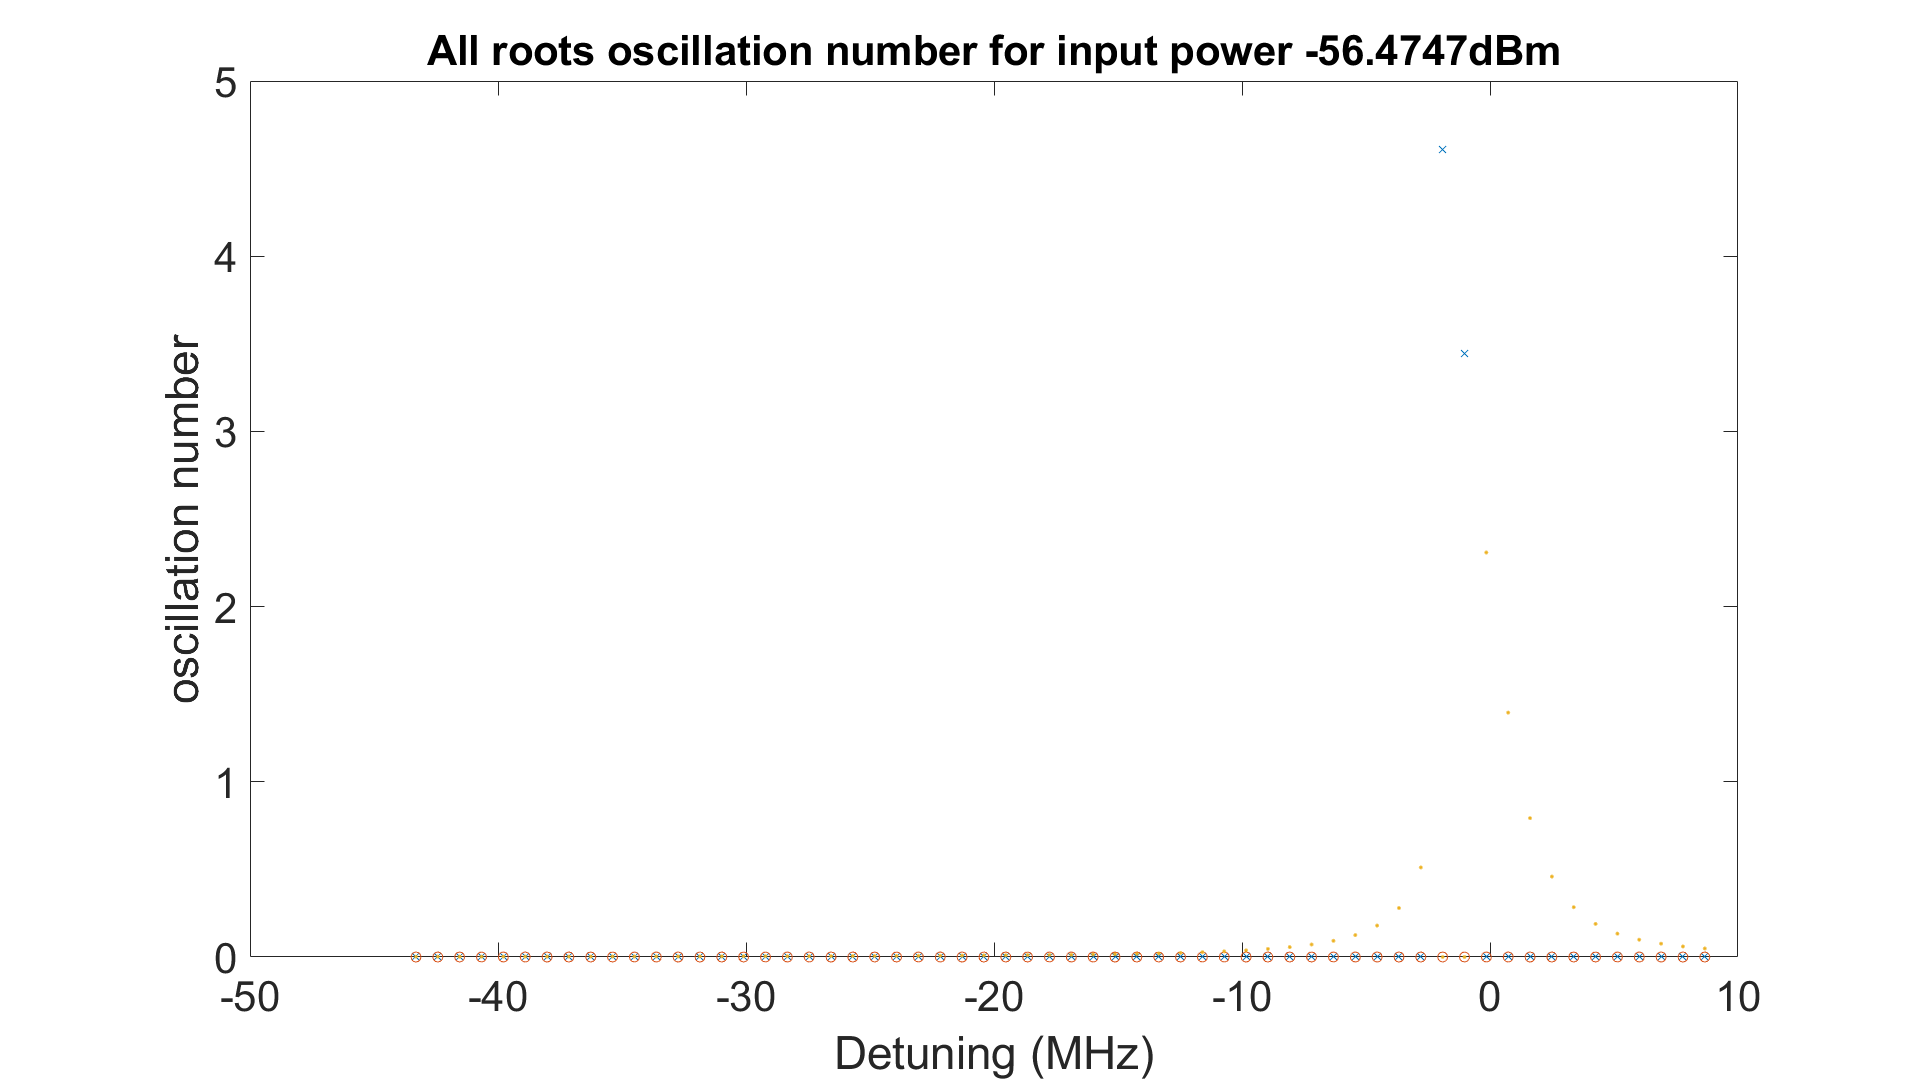

    % amp_roots(check_power_input,check_detuning_number,:)
    % check_value = kerr^2 .* amp_roots(check_power_input,check_detuning_number,:).^3 - 2*kerr.*detunings_array(check_power_input,check_detuning_number) .* amp_roots(check_power_input,check_detuning_number,:).^2  +...
    %     (detunings_array(check_power_input,check_detuning_number)^2 + kappa_tot^2/4) .* amp_roots(check_power_input,check_detuning_number,:) -...
    %     kappa_ext * power_input_array(check_power_input,check_detuning_number)
        
    % i = randi(100)
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['1st root oscillation number for input power ' num2str(power_input_in_dBm(i)) 'dBm'])
    % 
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['2nd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
    % 
    % figure
    % plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3))
    % xlabel('Detuning (Hz)')
    % ylabel('oscillation number')
    % title(['3rd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
    
    figure
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1),'x')
    hold on
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2),'o')
    plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3),'.')
    hold off
    xlabel('Detuning (MHz)')
    ylabel('oscillation number')
    title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) + input_attenuation) 'dBm'])

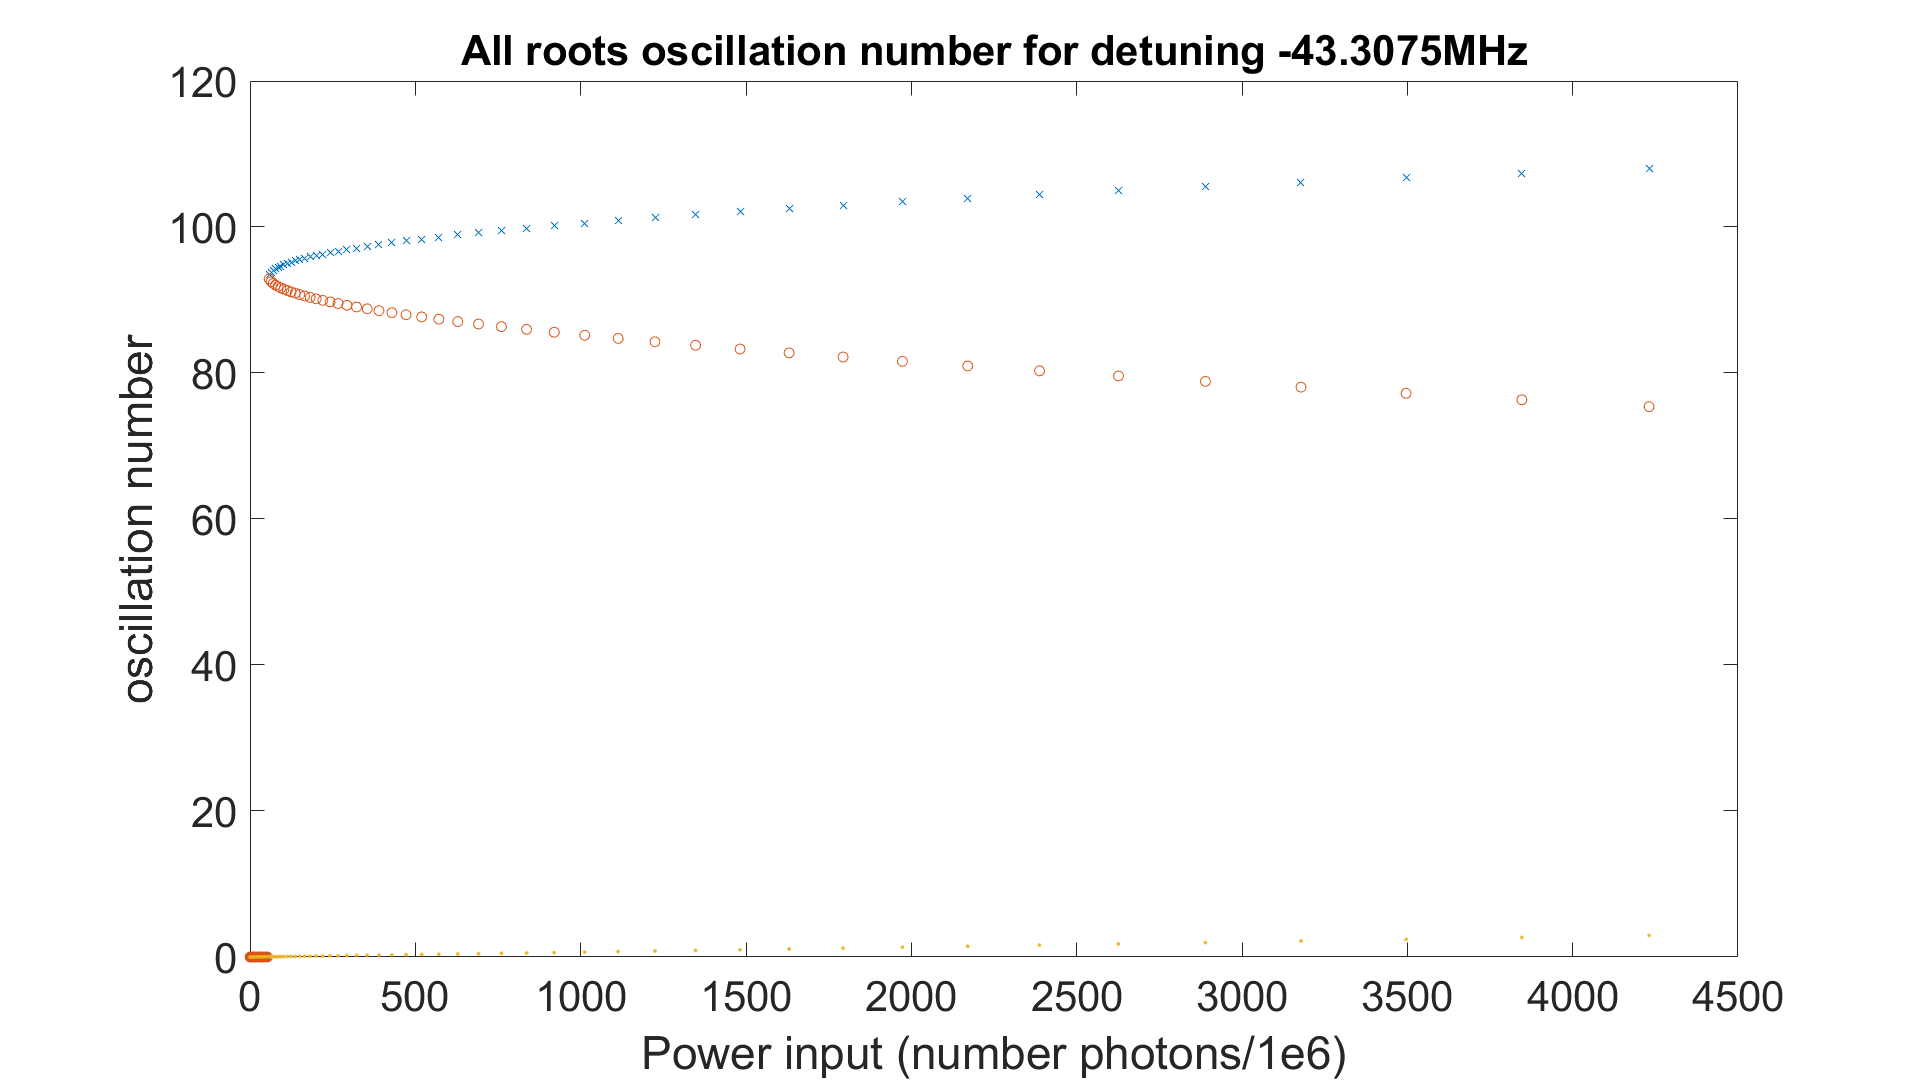

    
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['1st root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    % 
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['2nd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    % 
    % figure
    % plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3))
    % xlabel('Power input (number photons)')
    % ylabel('oscillation number')
    % title(['3rd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
    
    figure
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1),'x')
    hold on
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2),'o')
    plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3),'.')
    hold off
    xlabel('Power input (number photons/1e6)')
    ylabel('oscillation number')
    title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

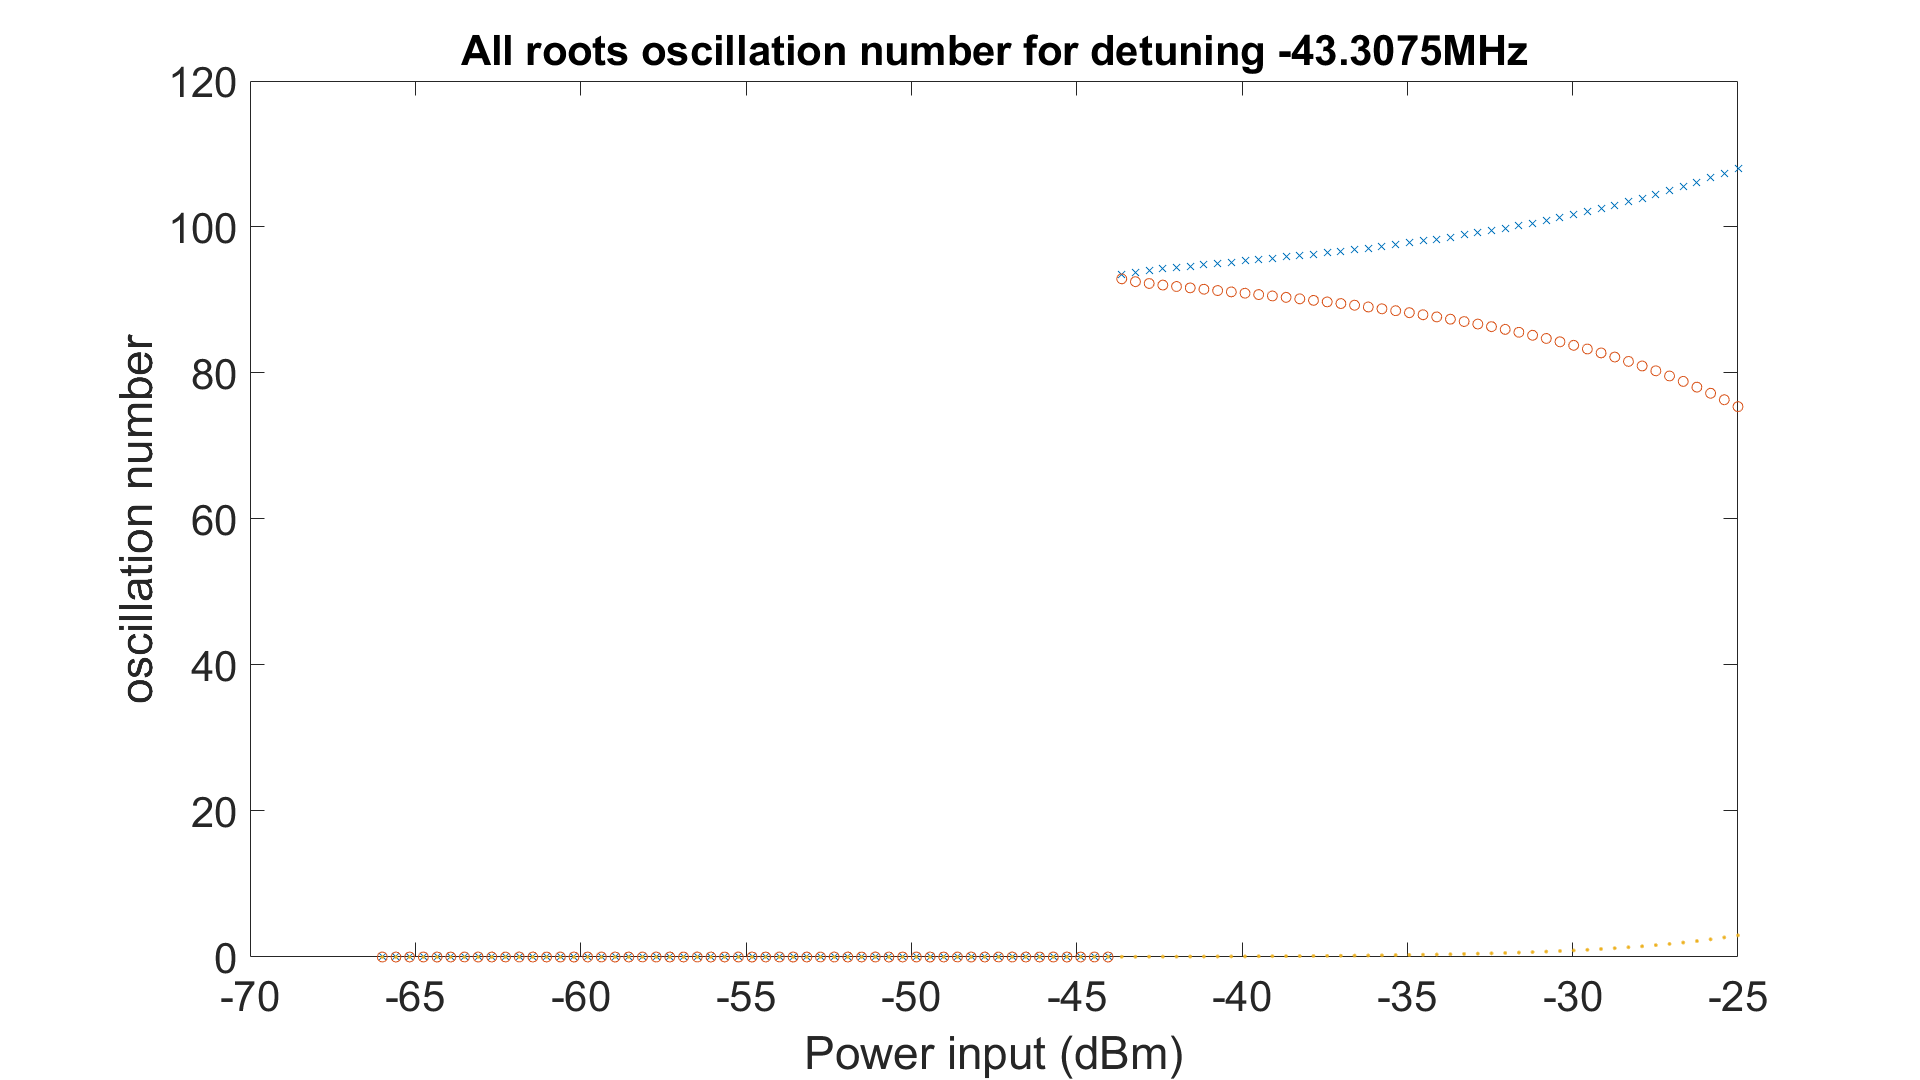

    
    figure
    plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + input_attenuation, amp_roots(:,check_detuning_number,1),'x')
    hold on
    plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + input_attenuation, amp_roots(:,check_detuning_number,2),'o')
    plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + input_attenuation, amp_roots(:,check_detuning_number,3),'.')
    hold off
    xlabel('Power input (dBm)')
    ylabel('oscillation number')
    title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

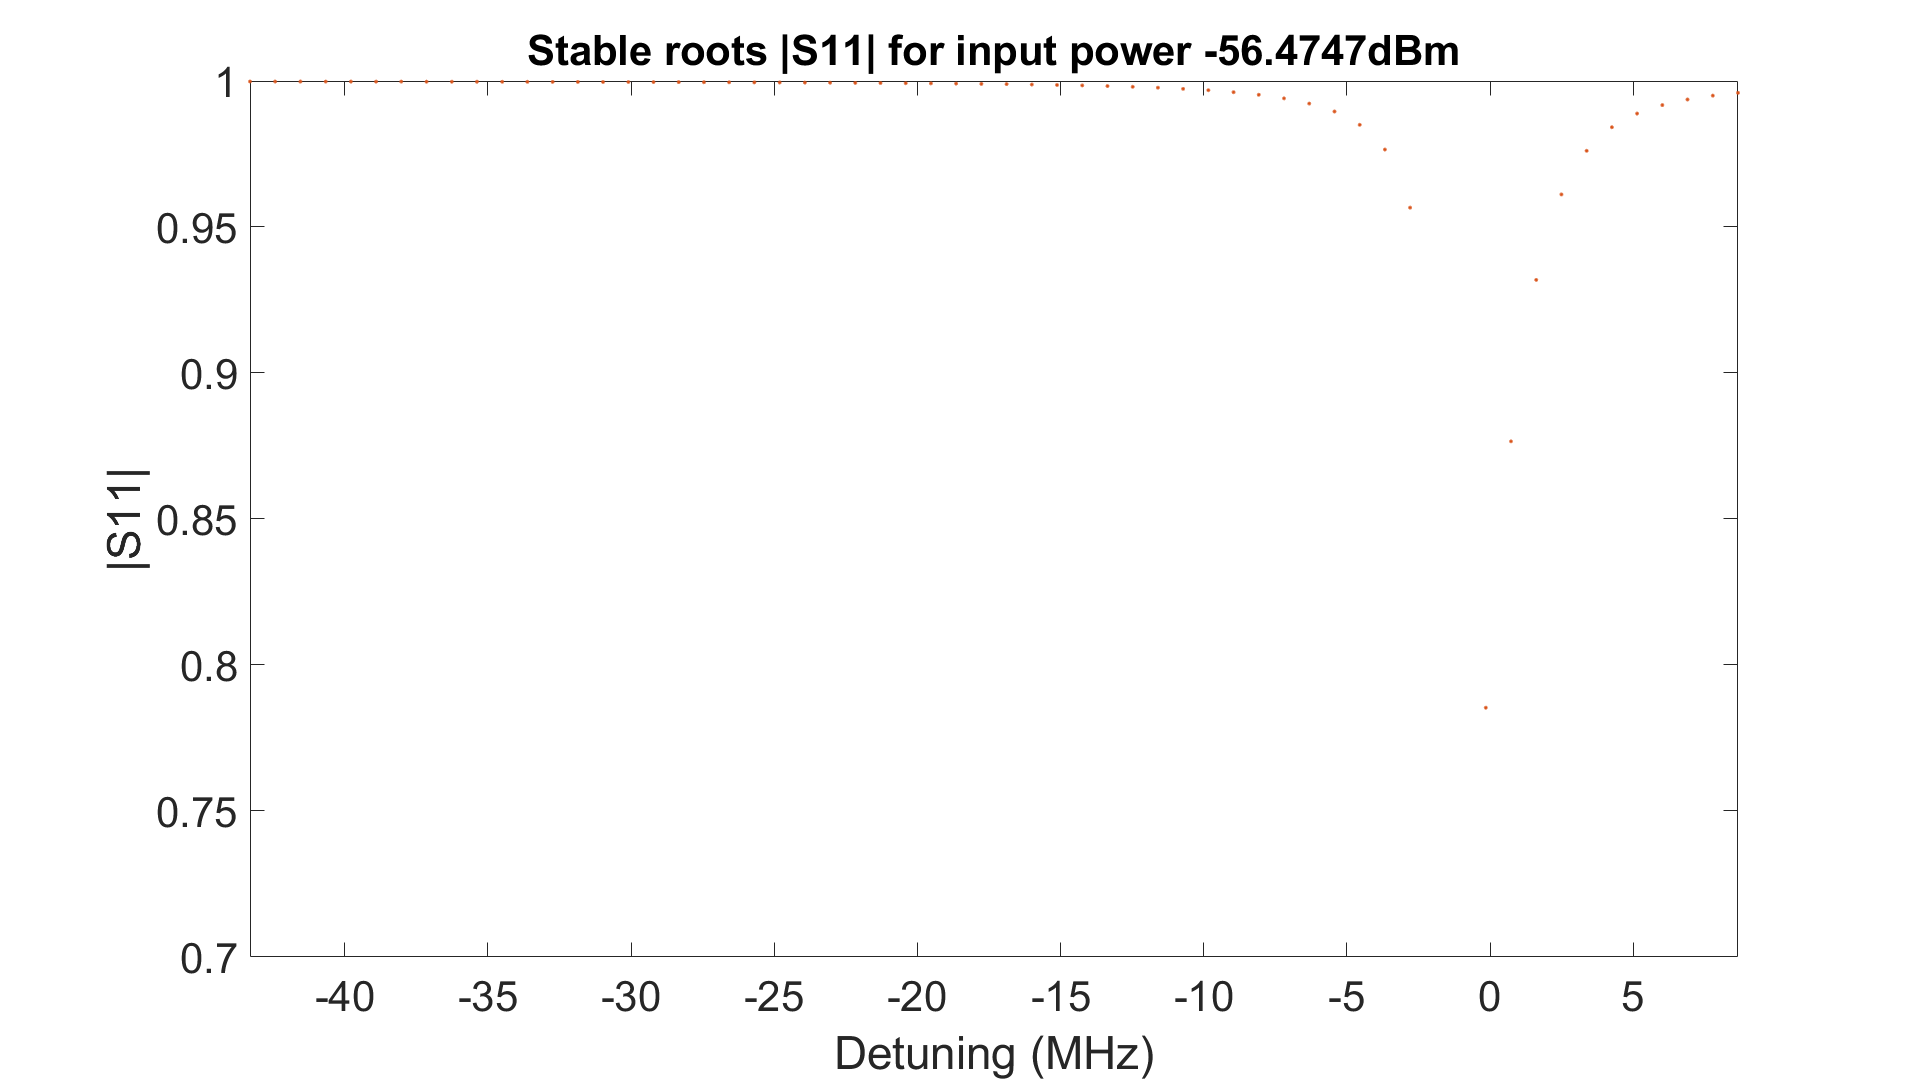

    
    figure
    plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,1)),'x')
    hold on
    % plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,2)),'o')
    plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,3)),'.')
    hold off
    xlabel('Detuning (MHz)')
    ylabel('|S11|')
    axis([detunings(1) detunings(end) .7 1])
    title(['Stable roots |S11| for input power ' num2str(power_input_in_dBm(check_power_input) + input_attenuation) 'dBm'])

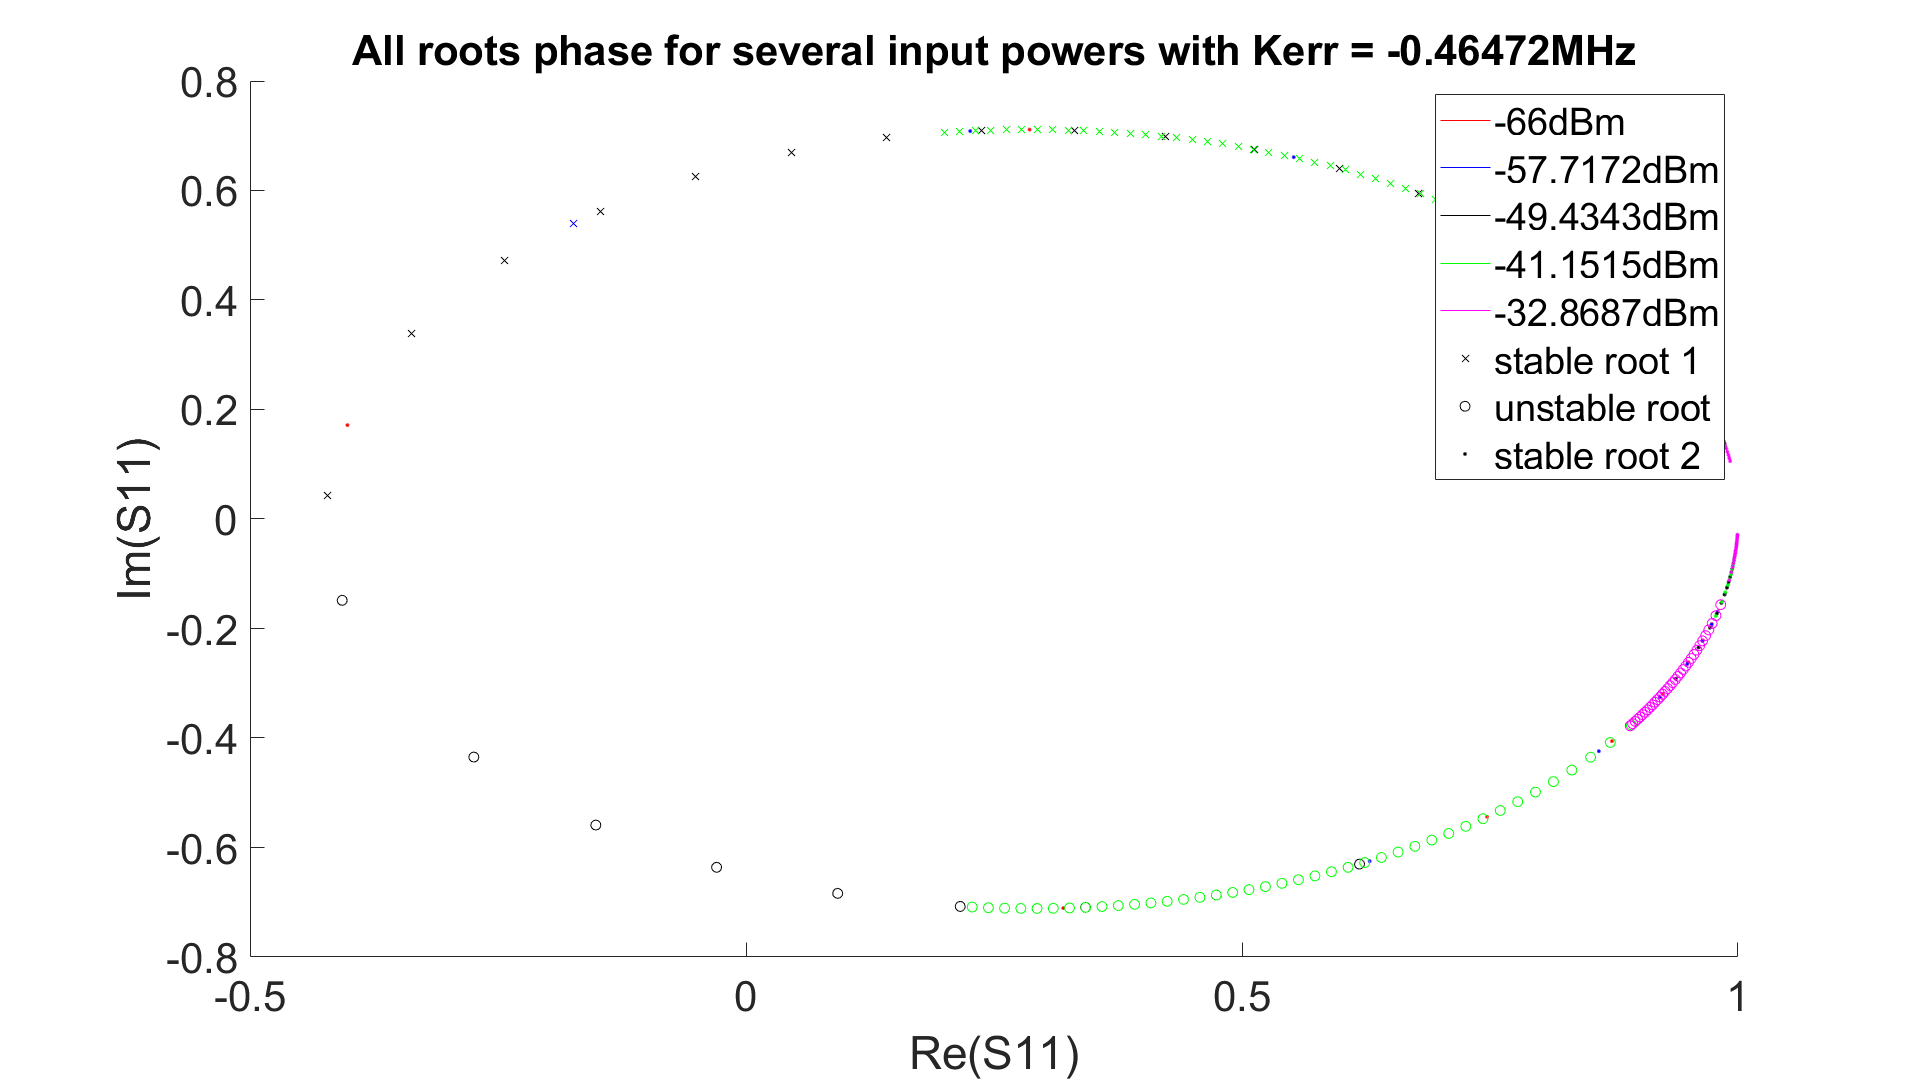

    
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(real(s11_root_1_temp), imag(s11_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(real(s11_root_2_temp), imag(s11_root_2_temp),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(real(s11_root_3_temp), imag(s11_root_3_temp),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 3'])
        xlabel('Re(S11)')
        ylabel('Im(S11)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(8,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'kx');
    h(7) = plot(nan, nan, 'ko');    
    h(8) = plot(nan, nan, 'k.');
    legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off

    
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '^'];
        plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop, 'markersize', 12, 'linewidth',4)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop, 'markersize', 12, 'linewidth',4)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop, 'markersize', 12, 'linewidth',4)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots S11 phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(8,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'kx');
    h(7) = plot(nan, nan, 'ko');    
    h(8) = plot(nan, nan, 'k.');
    legend (h, [num2str(power_input_in_dBm(1)) 'dBm'], [num2str(power_input_in_dBm(21)) 'dBm'], [num2str(power_input_in_dBm(41)) 'dBm'],...
        [num2str(power_input_in_dBm(61)) 'dBm'], [num2str(power_input_in_dBm(81)) 'dBm'])%, 'stable root 1', 'unstable root', 'stable root 2')

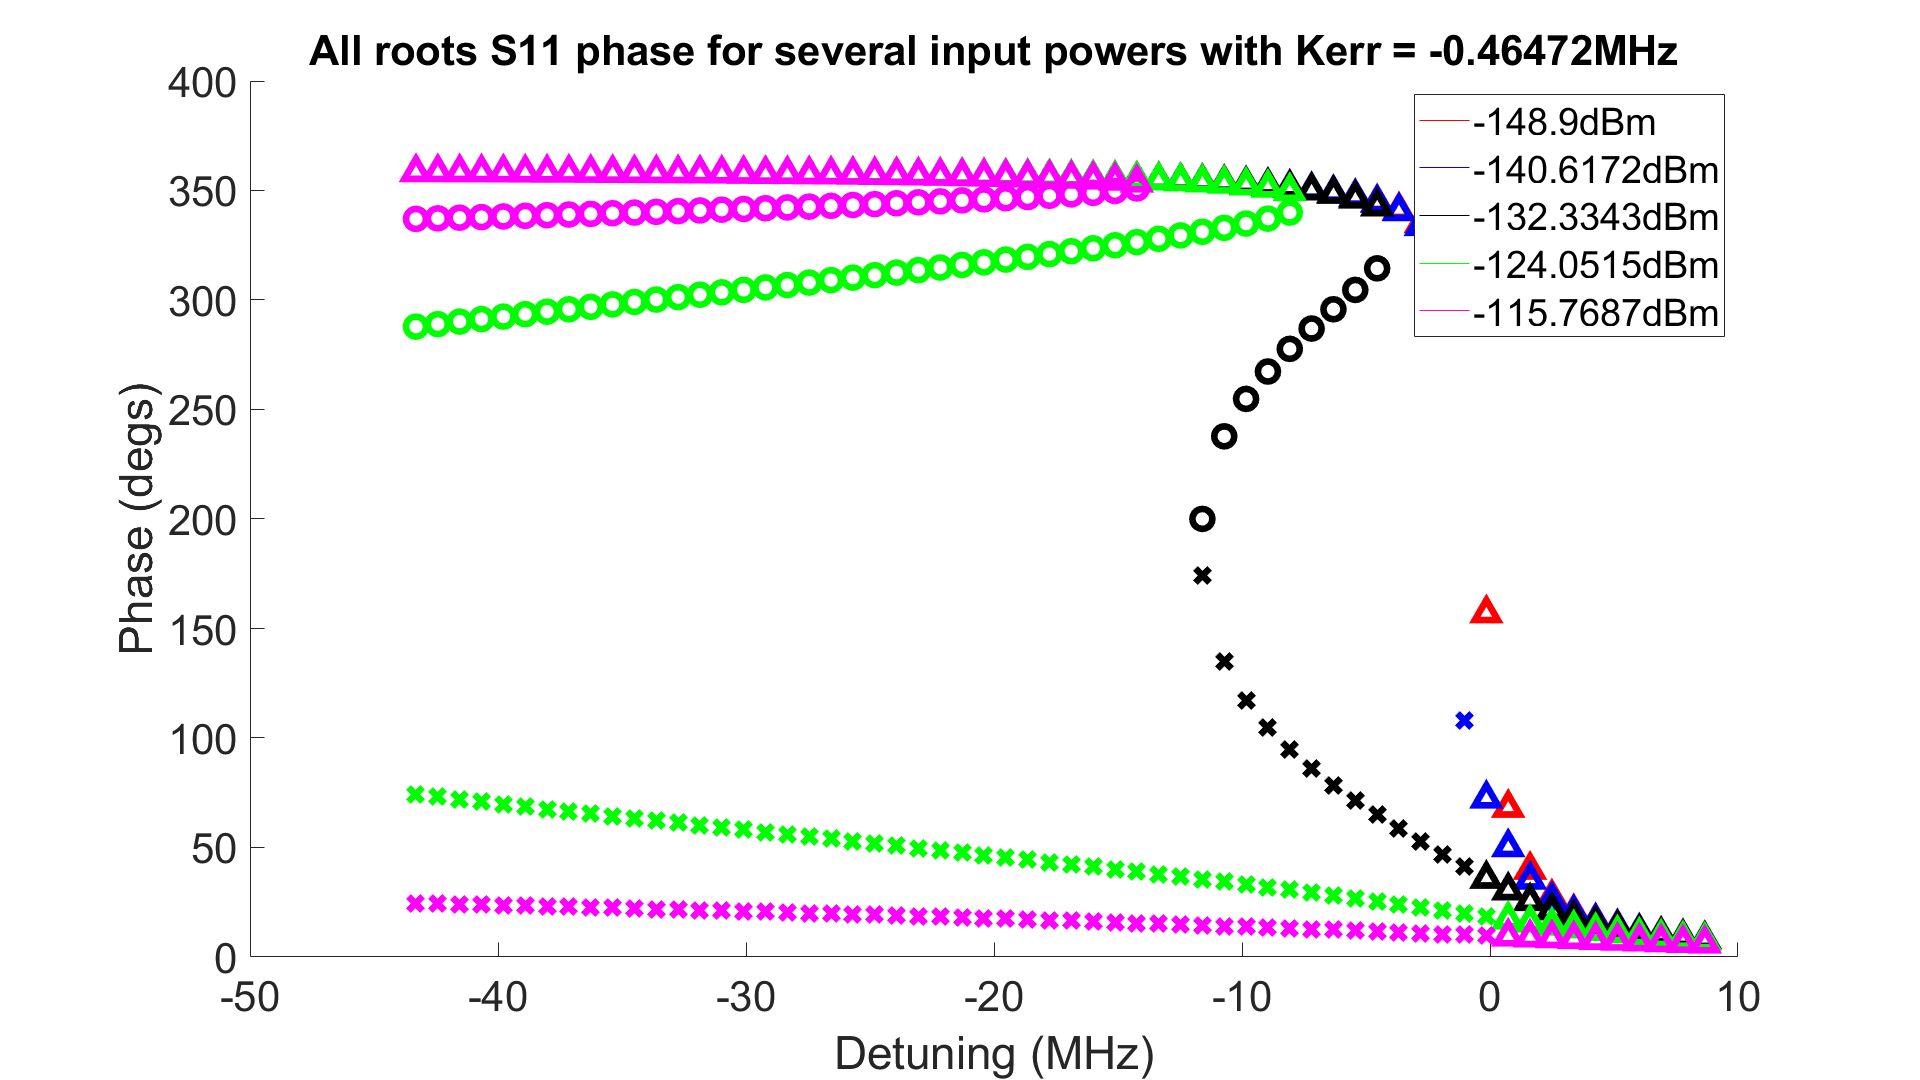

     hold off

    
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '^'];
        plot(detunings_array_1, abs(s11_root_1_temp),root_1_color_prop, 'markersize', 12, 'linewidth',4)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2, abs(s11_root_2_temp),root_2_color_prop, 'markersize', 12, 'linewidth',4)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, abs(s11_root_3_temp),root_3_color_prop, 'markersize', 12, 'linewidth',4)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('|S11|')
        title(['All roots |S11| for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(8,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'kx');
    h(7) = plot(nan, nan, 'ko');    
    h(8) = plot(nan, nan, 'k.');
    legend (h, [num2str(power_input_in_dBm(1)) 'dBm'], [num2str(power_input_in_dBm(21)) 'dBm'], [num2str(power_input_in_dBm(41)) 'dBm'],...
        [num2str(power_input_in_dBm(61)) 'dBm'], [num2str(power_input_in_dBm(81)) 'dBm'])%, 'stable root 1', 'unstable root', 'stable root 2')

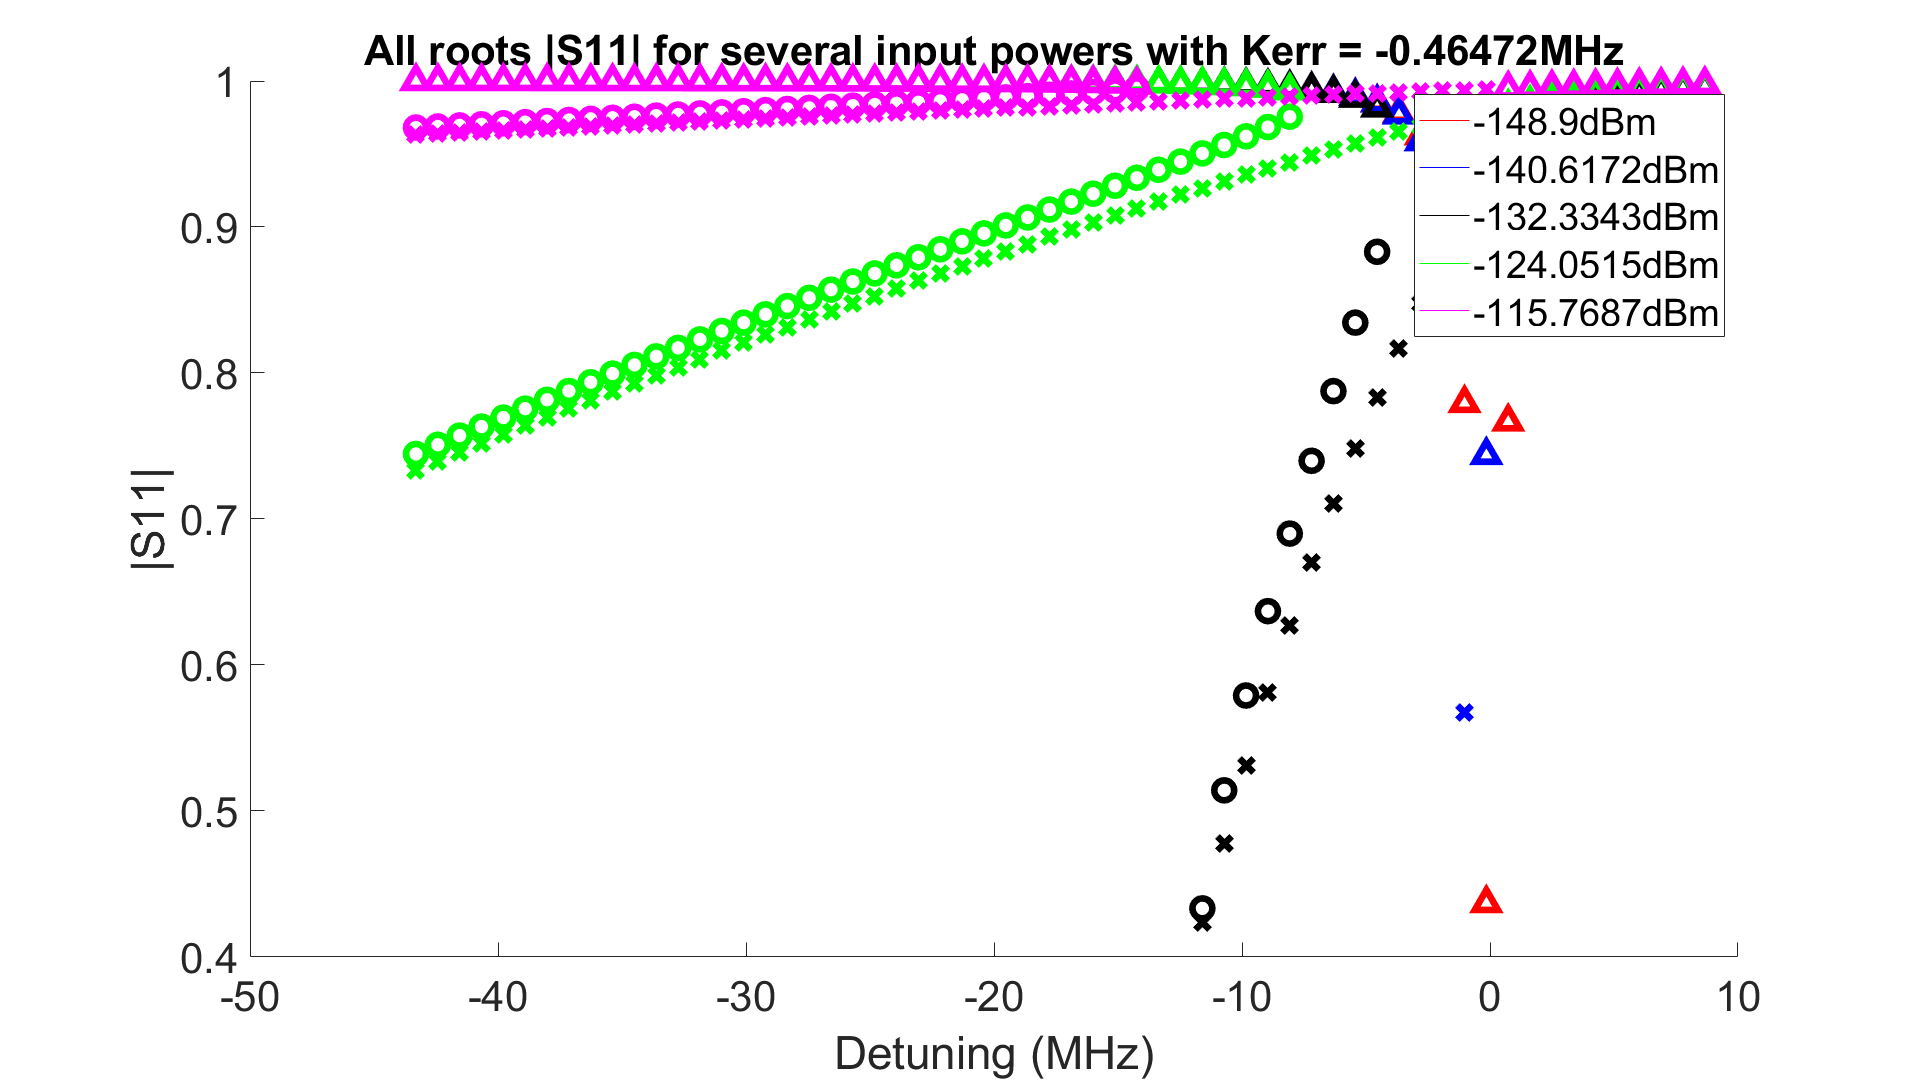

     hold off

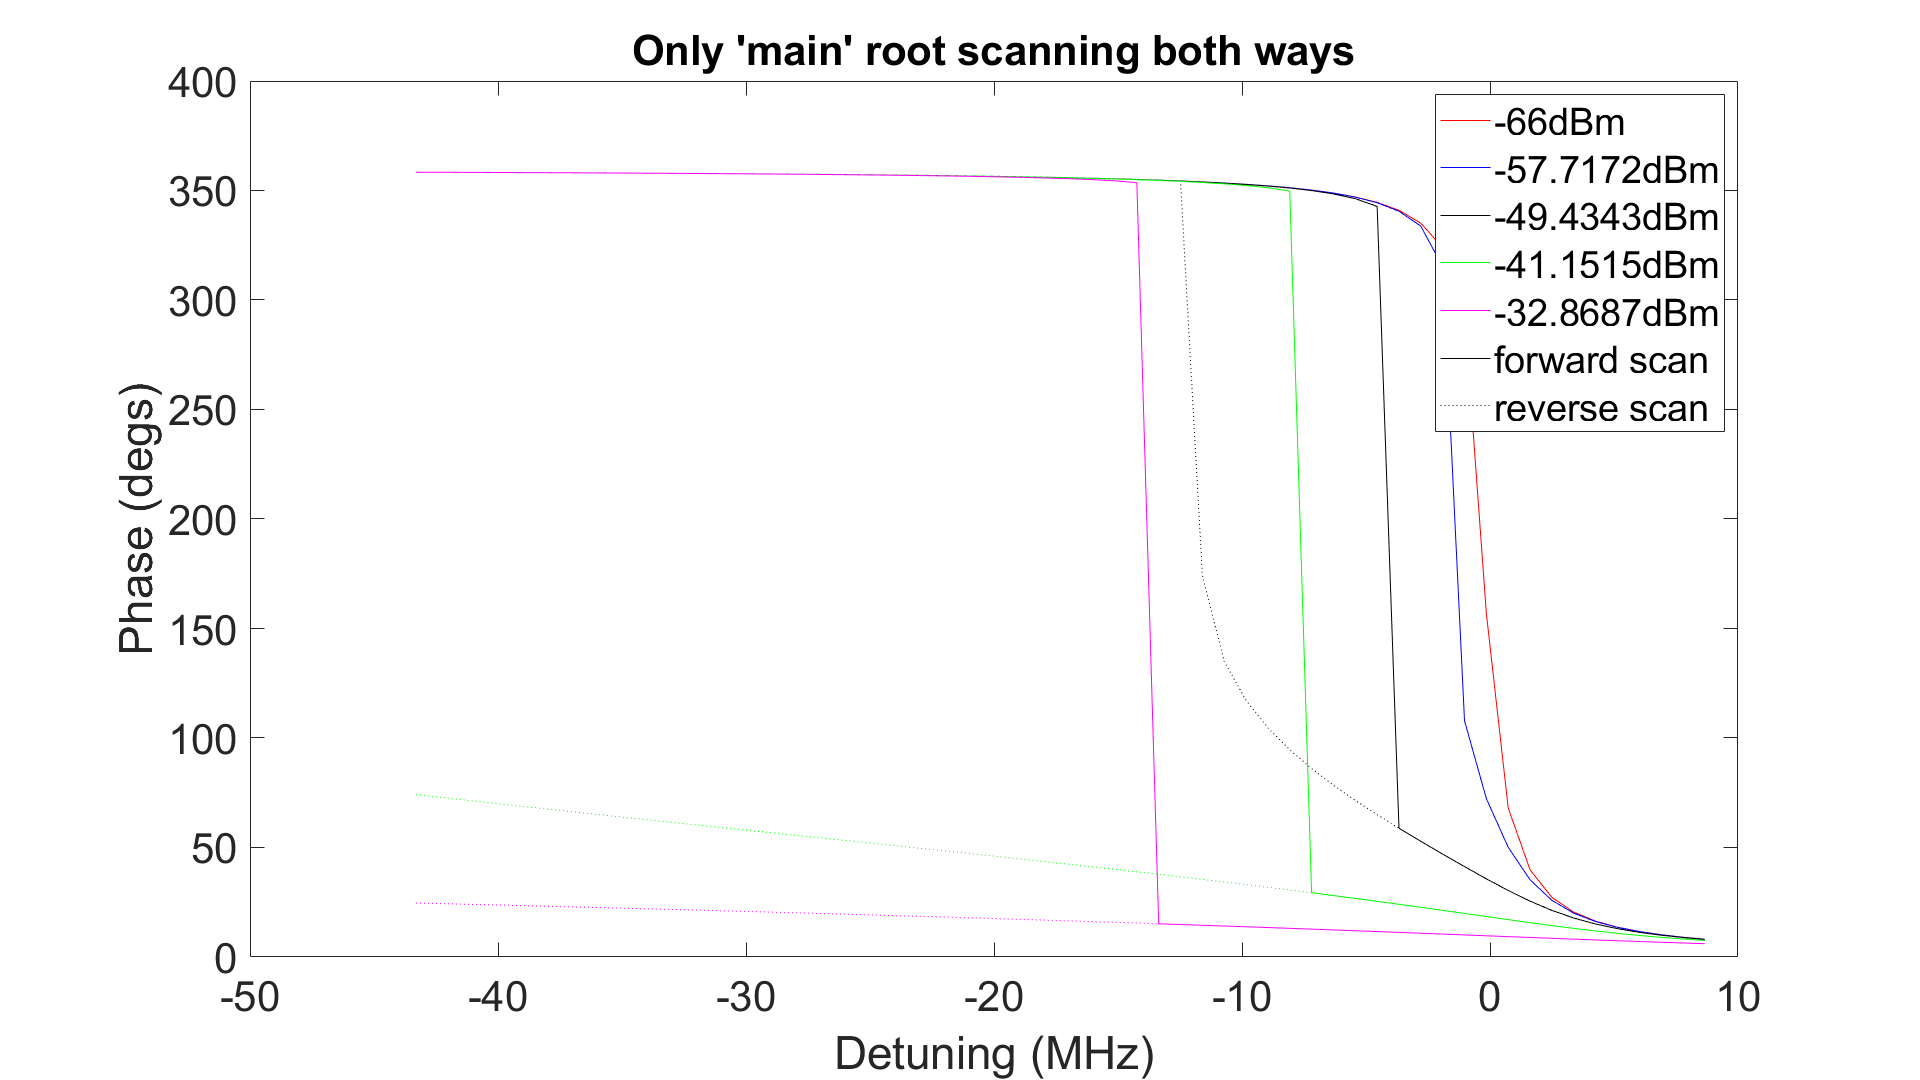

     
    i = 1;
    j = 1;
    figure
    color_array = ["-r", ":r", "-b", ":b", "-k", ":k", "-g", ":g", "-m", ":m"];
    % i_list = [];
    while i < 100
    %     i_list = [i_list; i];
        main_s11_temp_forward = main_s11_forward(i,:);
        detunings_array_1 = detunings_array(i,:);
        main_s11_temp_reverse = main_s11_reverse(i,:);
        plot(detunings_array, wrapTo360(180/pi*angle(main_s11_temp_forward)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
        hold on
        j = j + 1;
        plot(detunings_array, wrapTo360(180/pi*angle(main_s11_temp_reverse)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
        i = i + 20;
        j = j + 1;
    end
    xlabel('Detuning (MHz)')
    ylabel('Phase (degs)')
    title("Only 'main' root scanning both ways")
    h = zeros(5,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'k-');
    h(7) = plot(nan, nan, 'k:');
    legend (h,[num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + input_attenuation) 'dBm'], 'forward scan', 'reverse scan')
    hold off   

    
        figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        amp_roots_1_temp = amp_roots(i,:,1);
        detunings_array_1 (amp_roots == 5) = [];
        amp_roots_1_temp(amp_roots == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        amp_roots_2_temp = amp_roots(i,:,2);
        detunings_array_2 (amp_roots == 5) = [];
        amp_roots_2_temp(amp_roots == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        amp_roots_3_temp = amp_roots(i,:,3);
        detunings_array_3 (amp_roots == 5) = [];
        amp_roots_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '^'];
        plot(detunings_array_1, amp_roots_1_temp,root_1_color_prop, 'markersize', 12, 'linewidth',4)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2, amp_roots_2_temp,root_2_color_prop, 'markersize', 12, 'linewidth',4)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, amp_roots_3_temp,root_3_color_prop, 'markersize', 12, 'linewidth',4)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('Oscillation number')
        title(['All roots amplitude for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(8,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'kx');
    h(7) = plot(nan, nan, 'ko');    
    h(8) = plot(nan, nan, 'k.');
    legend (h, [num2str(power_input_in_dBm(1)) 'dBm'], [num2str(power_input_in_dBm(21)) 'dBm'], [num2str(power_input_in_dBm(41)) 'dBm'],...
        [num2str(power_input_in_dBm(61)) 'dBm'], [num2str(power_input_in_dBm(81)) 'dBm'])%, 'stable root 1', 'unstable root', 'stable root 2')

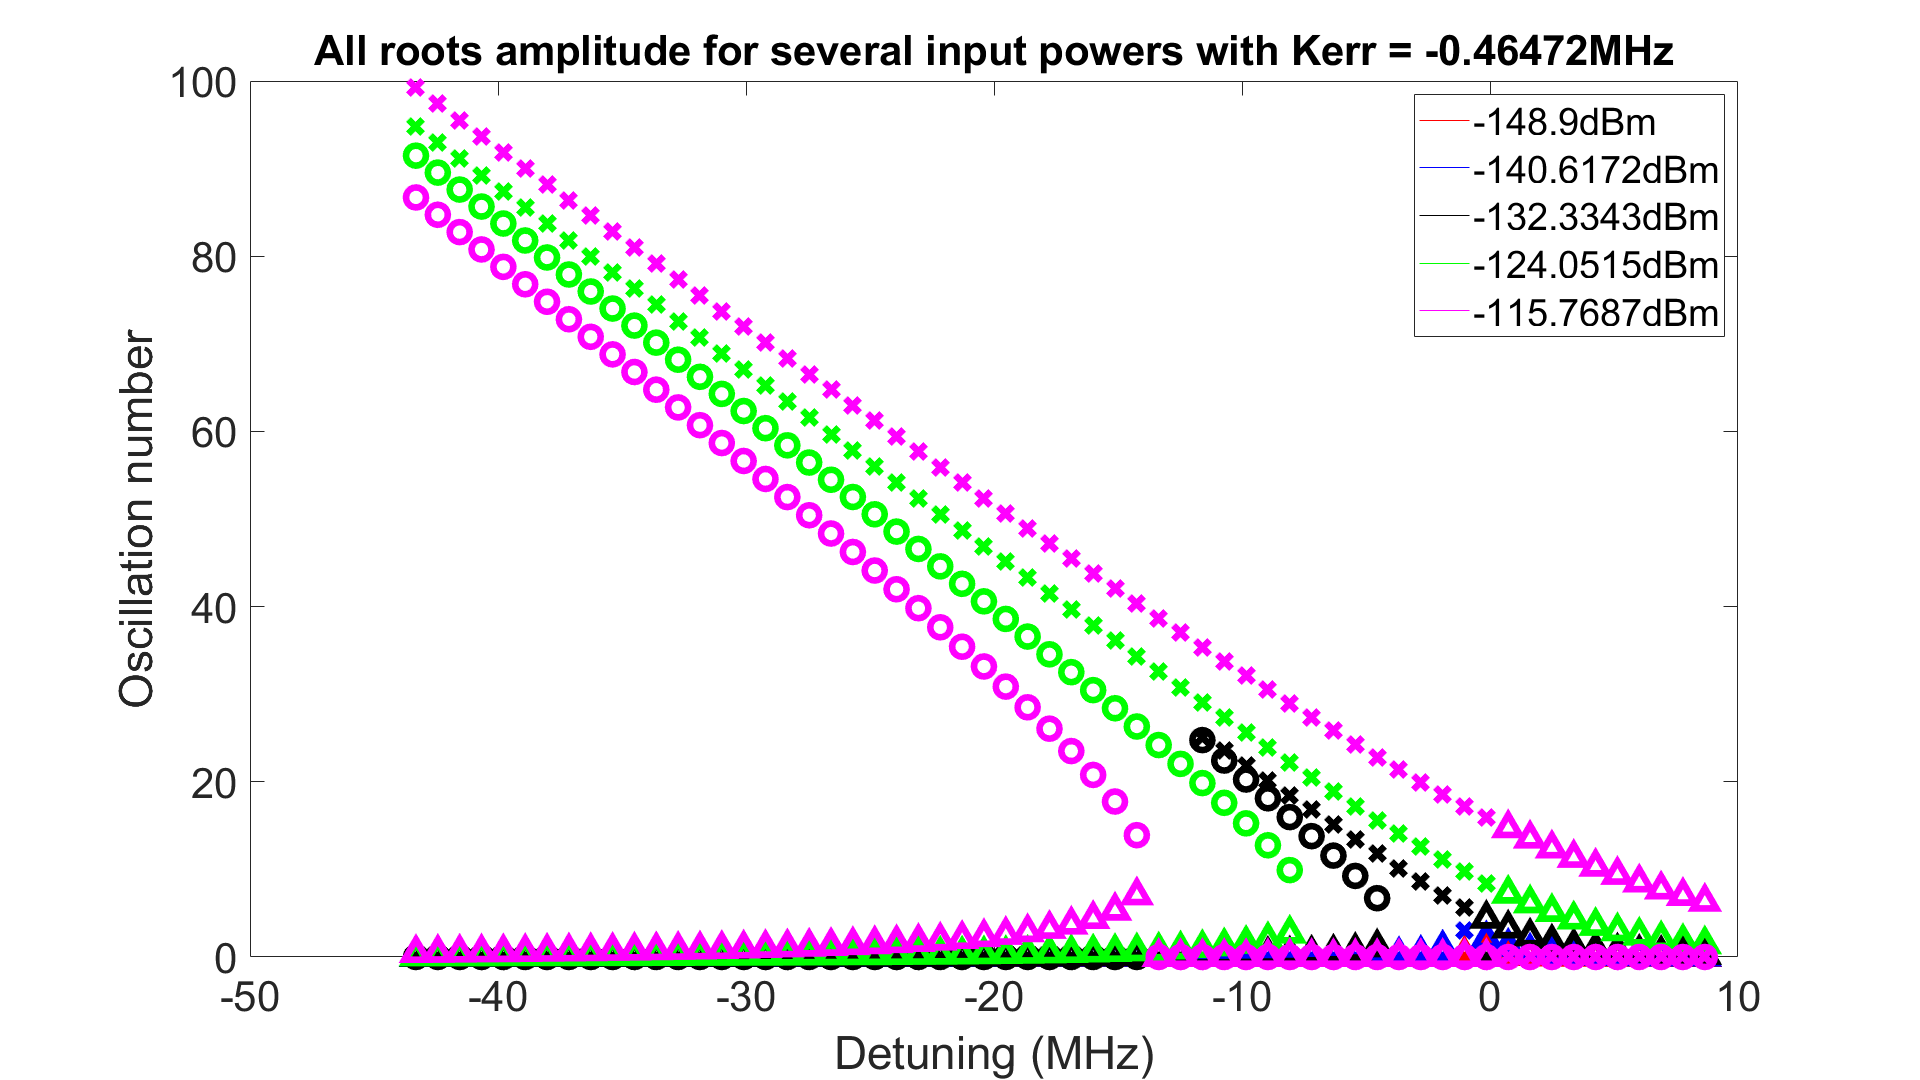

     hold off

     
    i = 1;
    j = 1;
    figure
    color_array = ["-r", ":r", "-b", ":b", "-k", ":k", "-g", ":g", "-m", ":m"];
    % i_list = [];
%     while i < 100
%     %     i_list = [i_list; i];
%         main_s11_temp_forward = main_s11_forward(i,:);
%         detunings_array_1 = detunings_array(i,:);
%         main_s11_temp_reverse = main_s11_reverse(i,:);
%         plot(detunings_array, wrapTo180(180/pi*angle(main_s11_temp_forward)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
%         hold on
%         j = j + 1;
%         plot(detunings_array, wrapTo180(180/pi*angle(main_s11_temp_reverse)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
%         i = i + 20;
%         j = j + 1;
%     end
%     xlabel('Detuning (MHz)')
%     ylabel('Phase (degs)')
%     title("Only 'main' root scanning both ways")
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     h(6) = plot(nan, nan, 'k-');
%     h(7) = plot(nan, nan, 'k:');
%     legend (h,[num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + input_attenuation) 'dBm'], 'forward scan', 'reverse scan')
%     hold off  

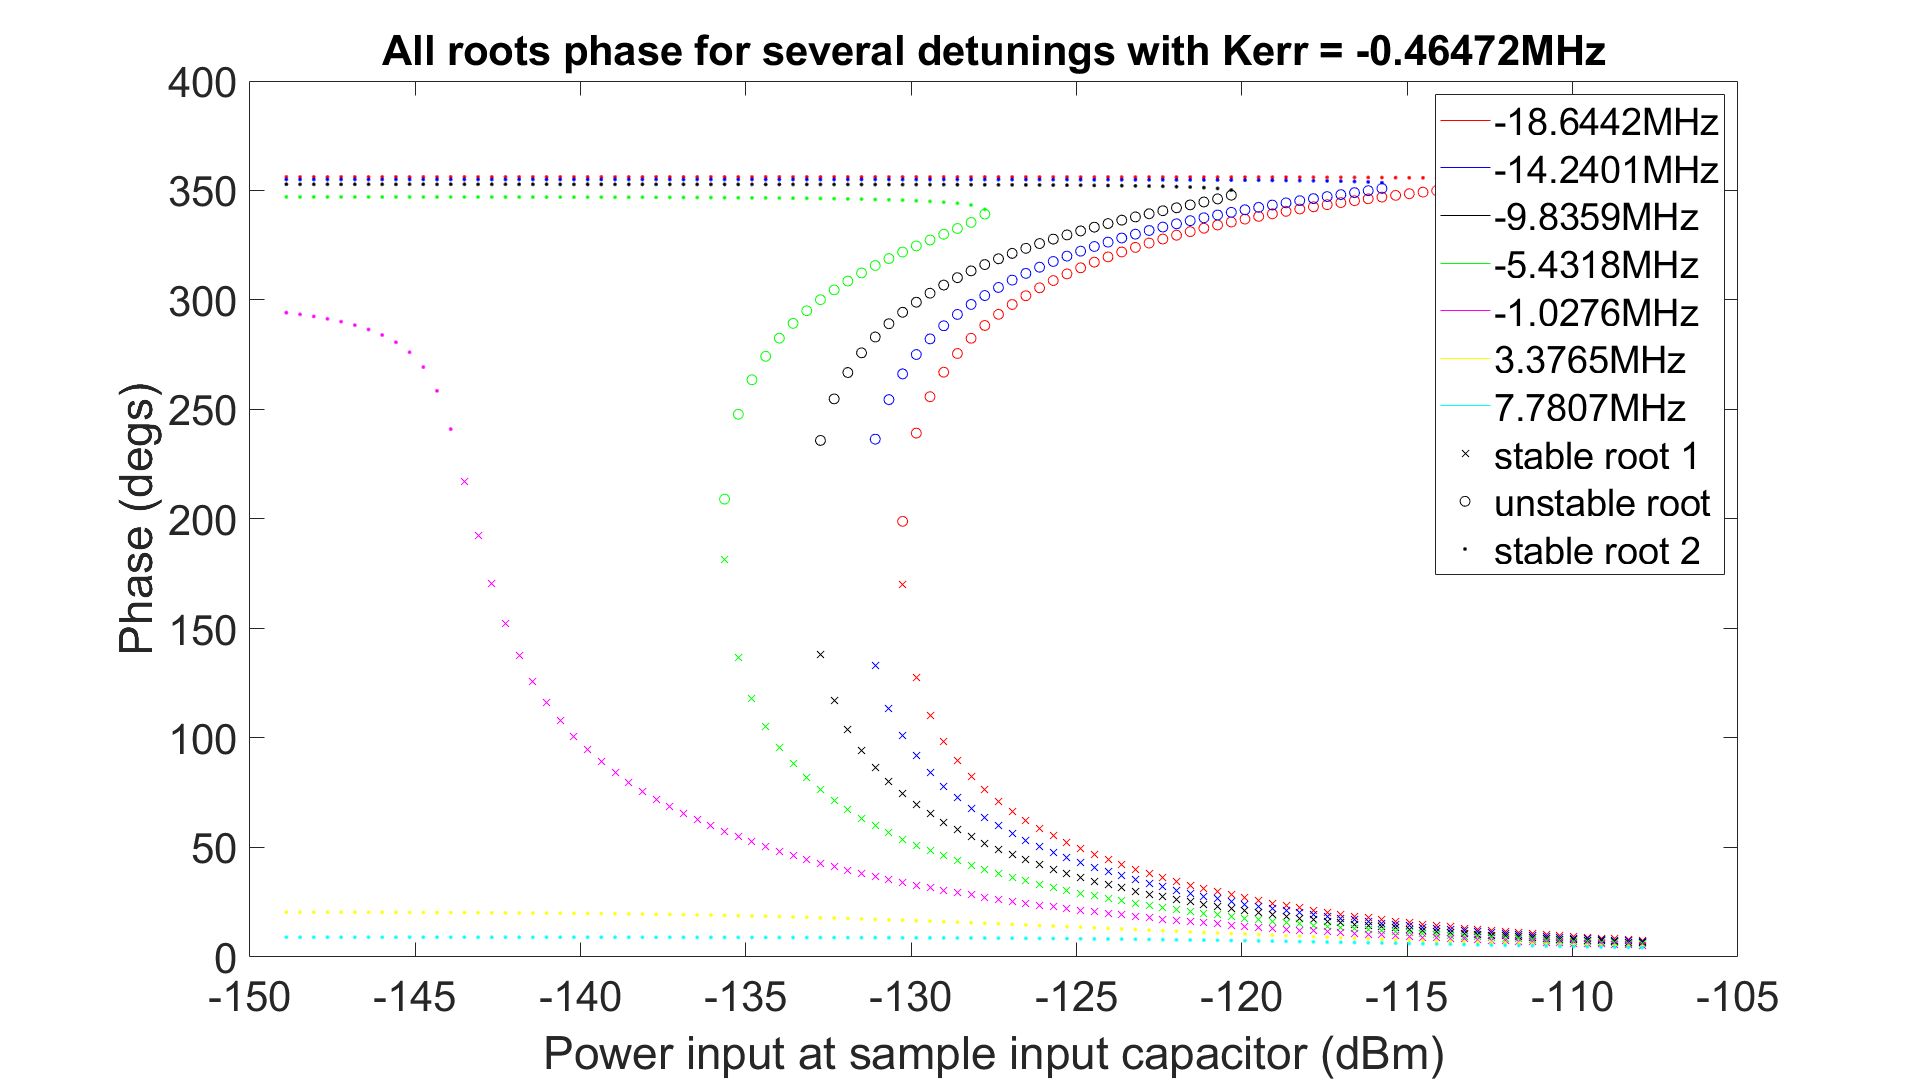

    figure
    color_array = ['r', 'b', 'k', 'g', 'm', 'y', 'c'];
    i_start = 29;
    i = i_start;
    i_step = 5;
    j = 1;
    while i<i_start + 7*i_step
%         power_input_array_temp_1 = power_input_array(:,i);
        power_input_array_temp_1 = power_input_in_dBm;
        s11_root_1_temp = s11(:,i,1);
        power_input_array_temp_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
%         power_input_array_temp_2 = power_input_array(:,i);
        power_input_array_temp_2 = power_input_in_dBm;
        s11_root_2_temp = s11(:,i,2);
        power_input_array_temp_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
%         power_input_array_temp_3 = power_input_array(:,i);
        power_input_array_temp_3 = power_input_in_dBm;        
        s11_root_3_temp = s11(:,i,3);
        power_input_array_temp_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(power_input_array_temp_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(power_input_array_temp_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(power_input_array_temp_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 3'])
%         xlabel('Power Input (number photons (in millions))')
        xlabel('Power input at sample input capacitor (dBm)')
        ylabel('Phase (degs)')
        title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
        i = i + i_step;
        j = j + 1;
    end
    i = i_start;
    h = zeros(8,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'y');
    h(7) = plot(nan, nan, 'c');
    h(8) = plot(nan, nan, 'kx');
    h(9) = plot(nan, nan, 'ko');
    h(10) = plot(nan, nan, 'k.');
    legend (h,[num2str(detunings(i)) 'MHz'], [num2str(detunings(i + i_step)) 'MHz'], [num2str(detunings(i + 2*i_step)) 'MHz'],...
        [num2str(detunings(i + 3*i_step)) 'MHz'], [num2str(detunings(i + 4*i_step)) 'MHz'], [num2str(detunings(i + 5*i_step)) 'MHz'], [num2str(detunings(i + 6*i_step)) 'MHz'], ...
        'stable root 1', 'unstable root', 'stable root 2')
    hold off

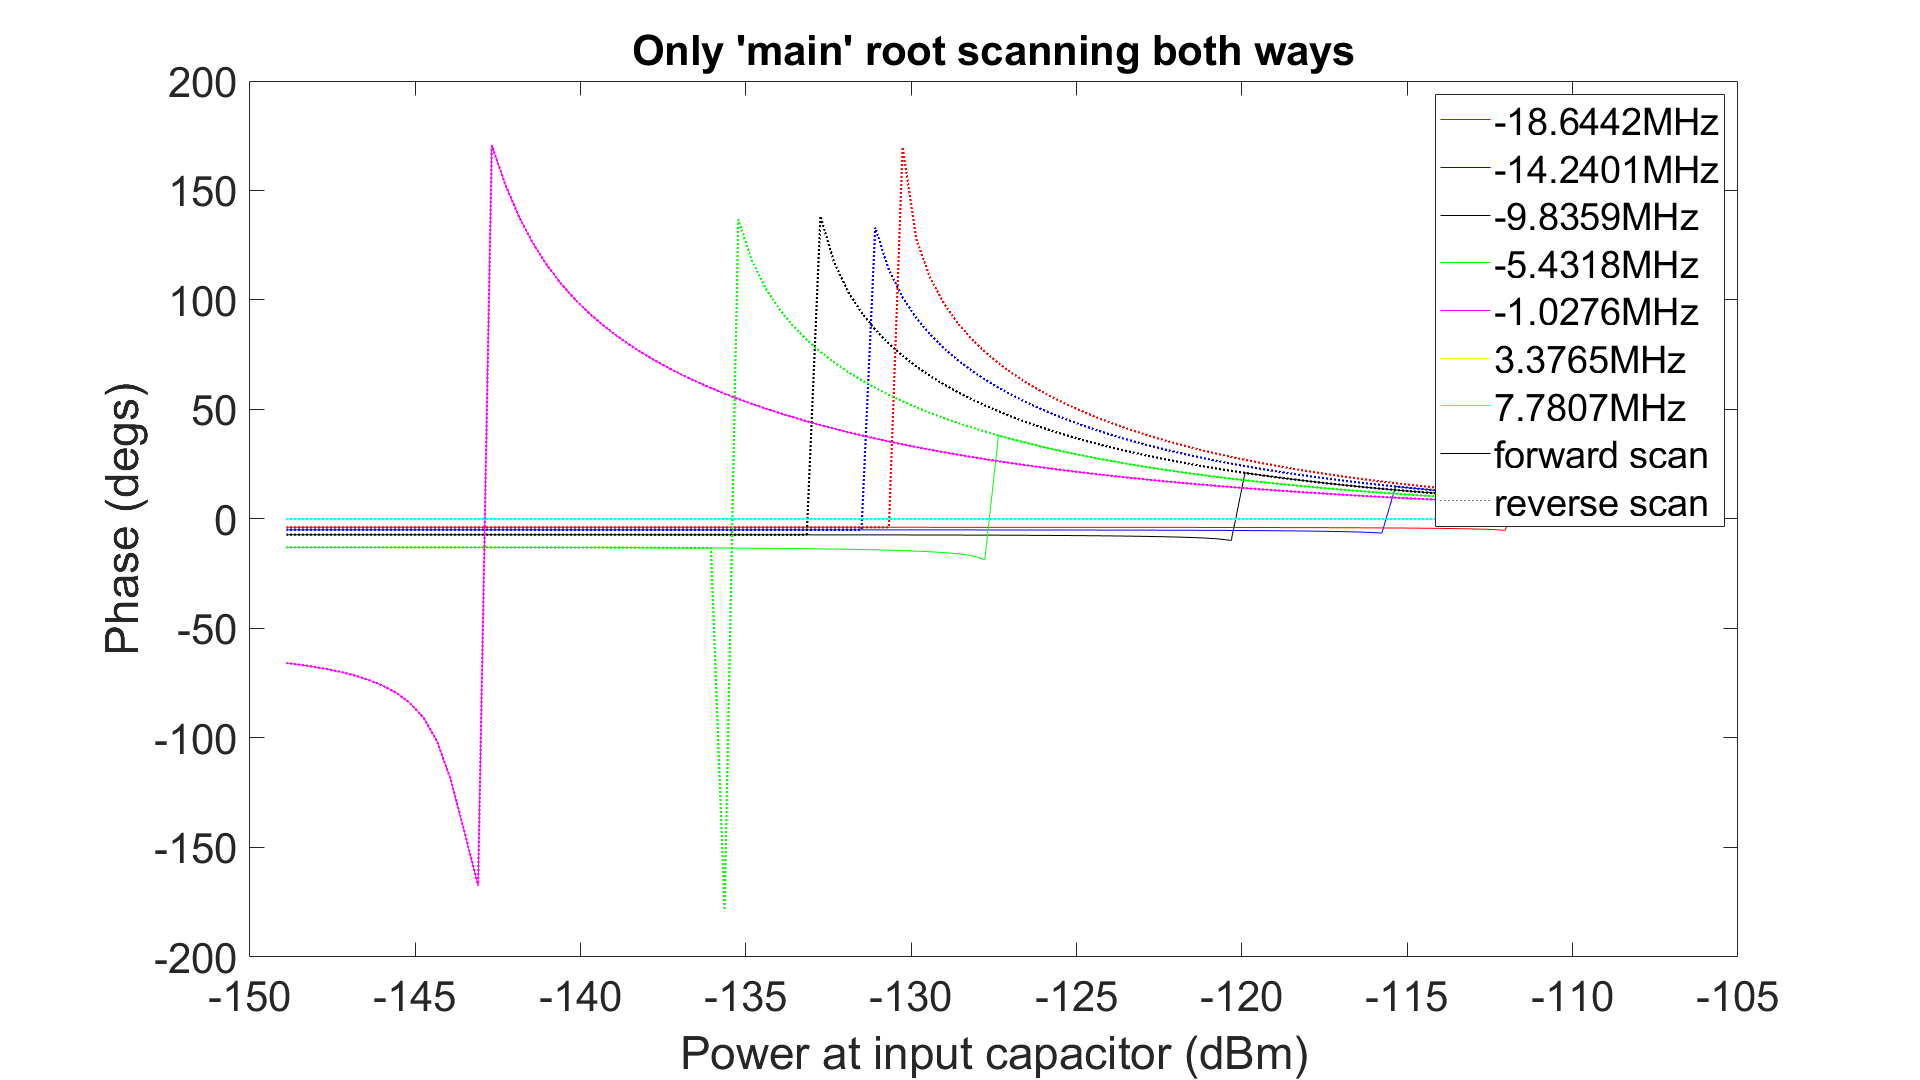

% end    
    i = i_start;
    j = 1;
    number = 0;
    figure
    color_array = ["-r", ":r", "-b", ":b", "-k", ":k", "-g", ":g", "-m", ":m", "-y", ":y", "-c", ":c"];
    while i < i_start + 7*i_step
    %     i_list = [i_list; i];
        main_s11_temp_forward = main_s11_forward_power(:,i);
        power_input_array_temp_1 = power_input_in_dBm;
        main_s11_temp_reverse = main_s11_reverse_power(:,i);
        plot(power_input_array_temp_1, wrapTo180(180/pi*angle(main_s11_temp_forward)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
        hold on
        j = j + 1;
        plot(power_input_array_temp_1, wrapTo180(180/pi*angle(main_s11_temp_reverse)), color_array(j),'LineWidth', 1.3)%, 'DisplayName', [num2str(power_input_in_dBm(i) + input_attenuation) 'dBm'])
        i = i + i_step;
        j = j + 1;
        number = number + 1;
    end
    i = i_start;
    xlabel('Power at input capacitor (dBm)')
    ylabel('Phase (degs)')
    title("Only 'main' root scanning both ways")
    h = zeros(5,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    h(6) = plot(nan, nan, 'y');
    h(7) = plot(nan, nan, 'c');
    h(8) = plot(nan, nan, 'k-');
    h(9) = plot(nan, nan, 'k:');
    legend (h,[num2str(detunings(i)) 'MHz'], [num2str(detunings(i + i_step)) 'MHz'], [num2str(detunings(i + 2*i_step)) 'MHz'],...
        [num2str(detunings(i + 3*i_step)) 'MHz'], [num2str(detunings(i + 4*i_step)) 'MHz'], [num2str(detunings(i + 5*i_step)) 'MHz'], [num2str(detunings(i + 6*i_step)) 'MHz'], ...
        'forward scan', 'reverse scan')
    hold off   

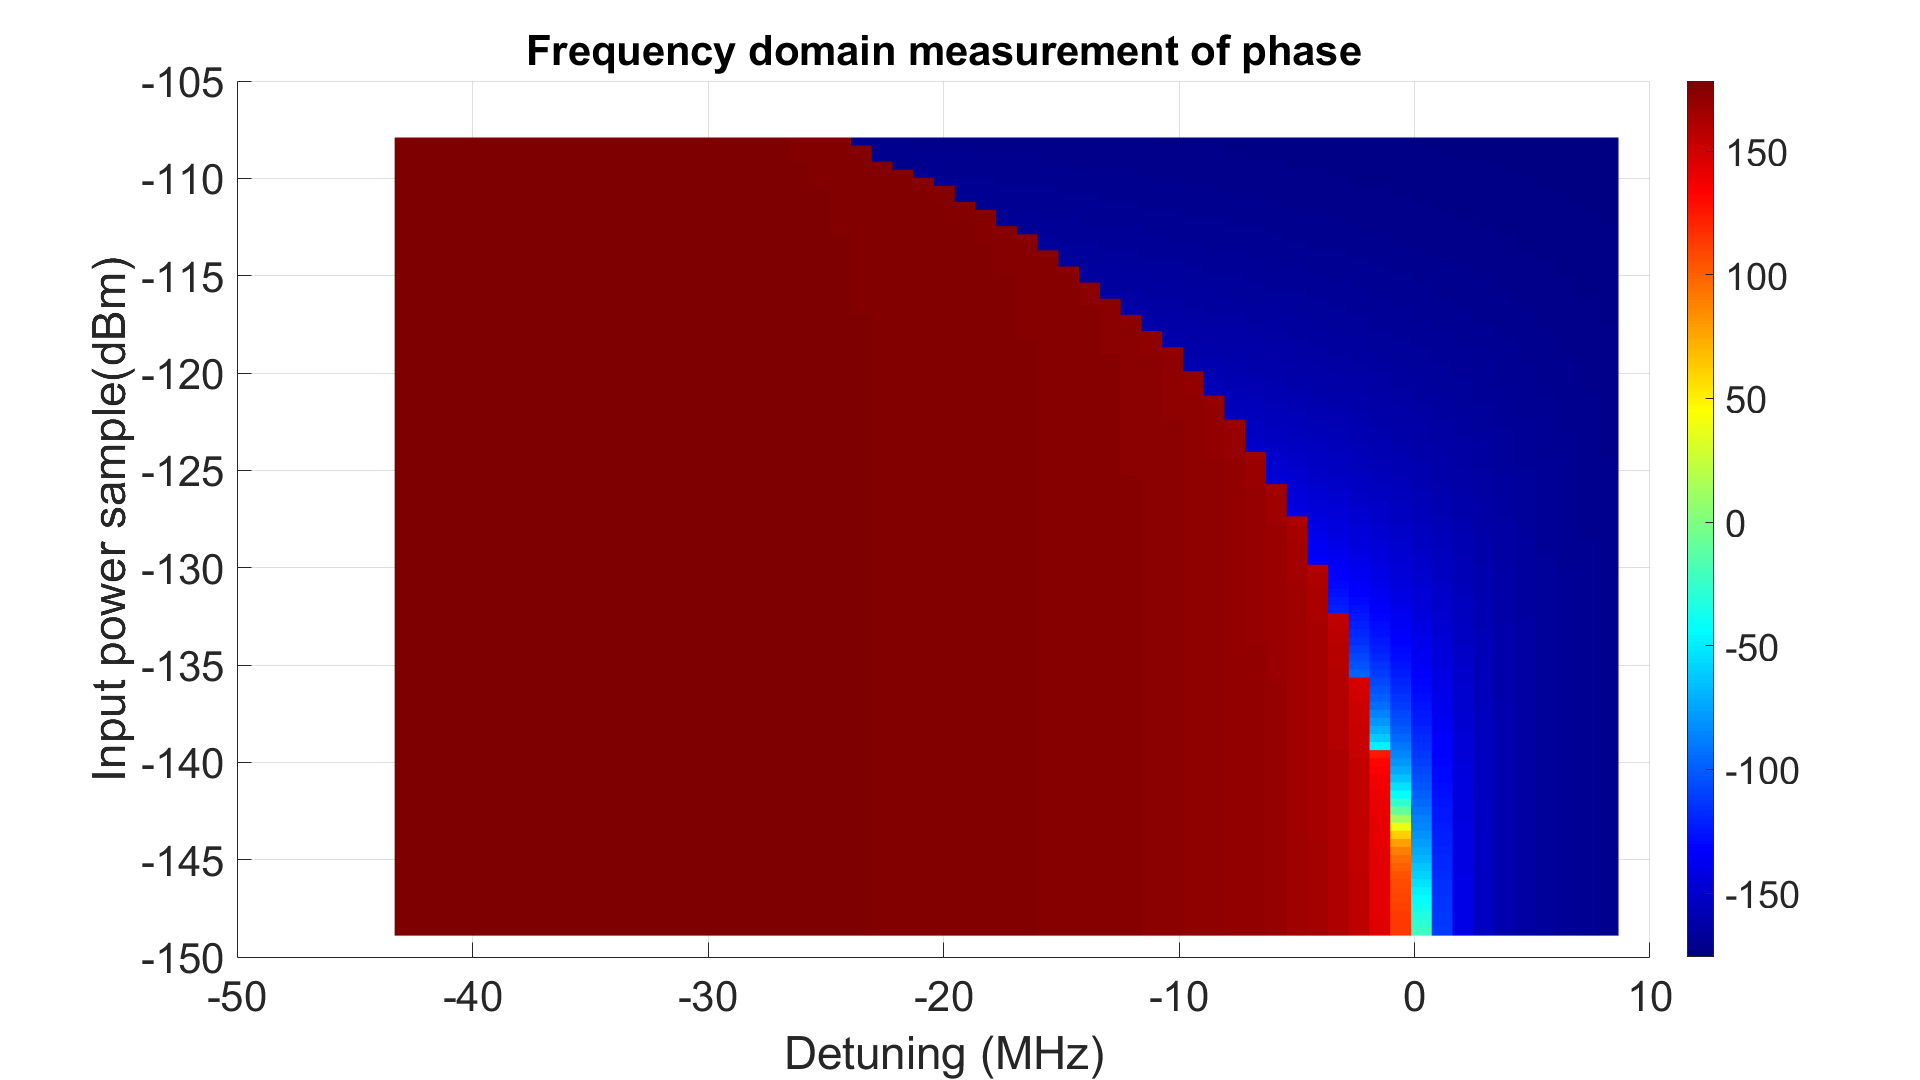

figure
surf(detunings, power_input_in_dBm, wrapTo360(180/pi*angle(main_s11_forward)) - 180,'LineStyle', 'none')
view(0,90)
xlabel('Detuning (MHz)')    
ylabel('Input power sample(dBm)')
colorbar
colormap(jet)
title('Frequency domain measurement of phase')